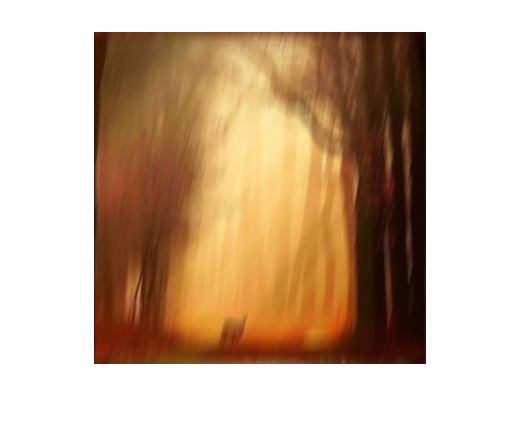

input = imread('hw2_files/Q3/1/1.png');
imshow(input)

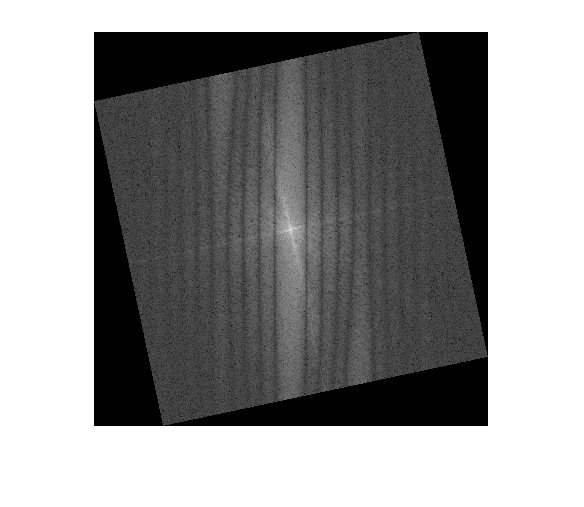

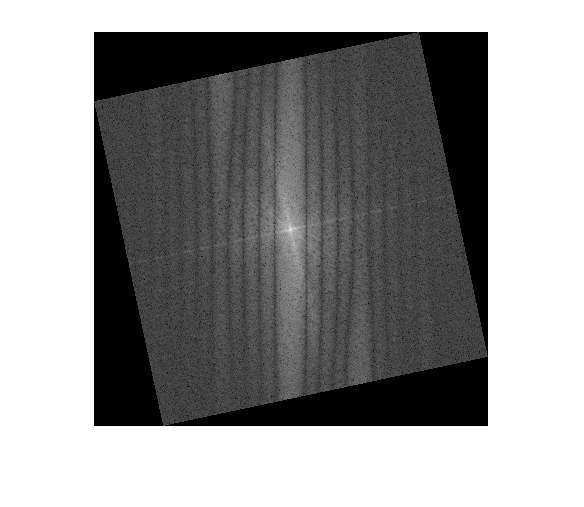

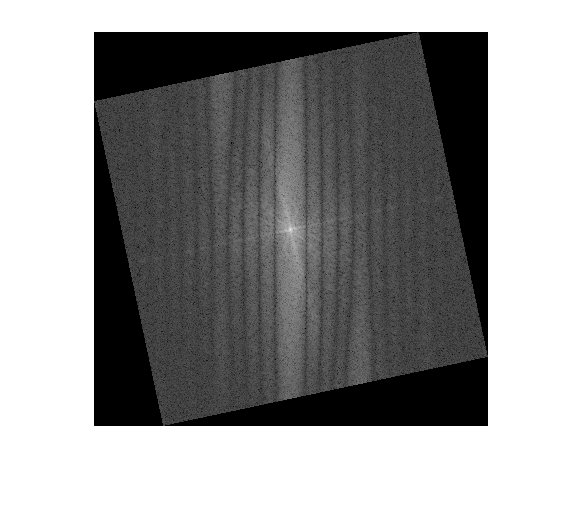

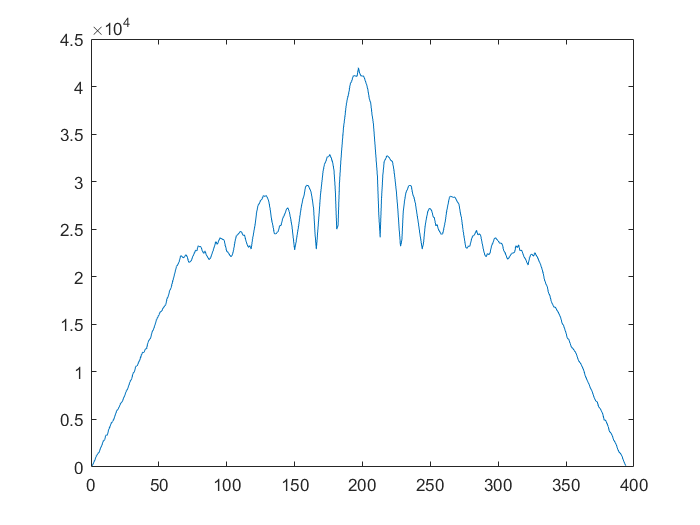

% [row,col,~] = size(input)
% imshow(input(:,:,2))
% fshift = fftshift(fft2(input(:,:,2)));
% magintude = 15*log(abs(fshift));
% imshow(uint8(magintude))
% 
% T = 1-imbinarize(uint8(magintude),"adaptive","Sensitivity",0.65)
% imshow(T)
% 
% kernel = ones([3,3],"uint8")
% morph = imopen(T,kernel)
% kernel = ones([1,9],"uint8")
% morph = imclose(morph,kernel)
% imshow(morph)
% 
% BW1 = edge(morph,'Canny');
% imshow(morph)
% 
% [H,T,R] = hough(BW1);
% P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
% lines = houghlines(BW1,T,R,P,'FillGap',5,'MinLength',7);
% figure, imshow(uint8(magintude)), hold on
% max_len = 0;
% theta = lines(1).theta
% theta_r=180-theta
% 
% rotated = imrotate(uint8(magintude),theta)
% imshow(rotated)
% 
% proj = sum(rotated,1)
% xaxis = 1: length(proj)
% [val,maxIndex] = max(proj)
% figure
% plot(xaxis,proj)
% for i = 1:100
%     if proj(maxIndex-i) - proj(maxIndex-i-1) < -1000
%         index_1 = i;
%         break
%     end
% end
% for i = 1:100
%     if proj(maxIndex+i) - proj(maxIndex+i+1) < -1000
%         index_2 = i;
%         break
%     end
% end
% 
% if abs(index_1 - index_2) >= 5
%     index_1 = max([index_1, index_2])
%     index_2 = max([index_1, index_2])
% end
% 
% L = 2 * row / (index_1 + index_2)

for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    pic = WeinerFilter(input(:,:,i),h,10);
    input(:,:,i) = pic;
end

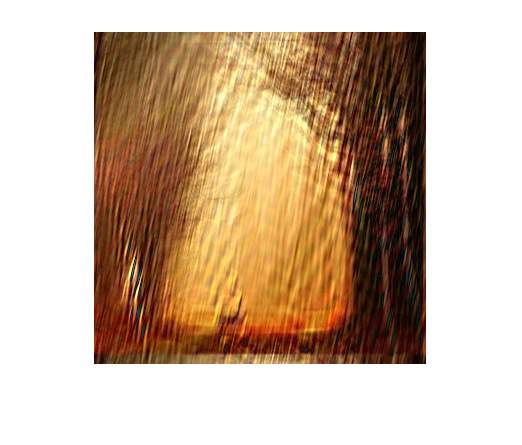

imshow(input);

function ret = WeinerFilter(layer, psf, K)
    [psf_row, psf_col] = size(psf);
    [row,col] = size(layer);
    psf_padded = zeros([row,col]);
    psf_padded(1:psf_row, 1:psf_col) = psf;
    psf_padded = psf_padded / sum(psf_padded,"all");
    psf_dft = fft2(psf_padded);
    
    testLayer = double(layer);
    estimated_nsr = K / var(testLayer(:));
    
    img_dft = fft2(layer);
    psf_dft_abs = abs(psf_dft).^2;
    dmp_factor = psf_dft_abs./(psf_dft_abs+estimated_nsr*ones([row,col]));
    layer_psf_fft_ratio = img_dft./psf_dft;
    result = abs(ifft2(dmp_factor.*layer_psf_fft_ratio));
    ret = uint8(result);
end

function ret = ConstraintLeastSquareFilter(layer,psf,gamma)
    [psf_row,psf_col] = size(psf);
end

function [theta,L] = DetectMotionParameters(layer)
    [row,~] = size(layer);
    fshift = fftshift(fft2(layer));
    magintude = 15*log(abs(fshift));
    imshow(uint8(magintude))
    
    T = 1-imbinarize(uint8(magintude),"adaptive","Sensitivity",0.65);
    kernel = ones([3,3],"uint8");
    morph = imopen(T,kernel);
    kernel = ones([1,9],"uint8");
    morph = imclose(morph,kernel);
    BW1 = edge(morph,'Canny');
    
    [H,T,R] = hough(BW1);
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    lines = houghlines(BW1,T,R,P,'FillGap',5,'MinLength',7);
    theta_rotate = lines(1).theta;
    theta = 180-theta_rotate;
    
    rotated = imrotate(uint8(magintude),theta_rotate);
    imshow(rotated)
    
    proj = sum(rotated,1);
    xaxis = 1: length(proj);
    figure;
    plot(xaxis,proj);
    
    [~,maxIndex] = max(proj);
    for i = 1:100
        if proj(maxIndex-i) - proj(maxIndex-i-1) < -1000
            index_1 = i;
            break
        end
    end
    for i = 1:100
        if proj(maxIndex+i) - proj(maxIndex+i+1) < -1000
            index_2 = i;
            break
        end
    end
    
    if abs(index_1 - index_2) >= 5
        index_1 = max([index_1, index_2]);
        index_2 = max([index_1, index_2]);
    end
    
    L = 2 * row / (index_1 + index_2);
end